# Example 6.16: Recursive Application of Convolution

Note: this script reproduces Example 6.16 (Section 6.3.4) of **Statistics for Chemical Engineers**: repeated convolution of a pdf with itself. Victor Z UW-Madison, 2019 illustrate central limit using convolutions

clc;  clear all; close all hidden; format short;

## Pdf

get pdf

t=linspace(0,10,100);
f=unifpdf(t,4,6);

## Repeated convolutions

show that repetitive convolutions yield Gaussian

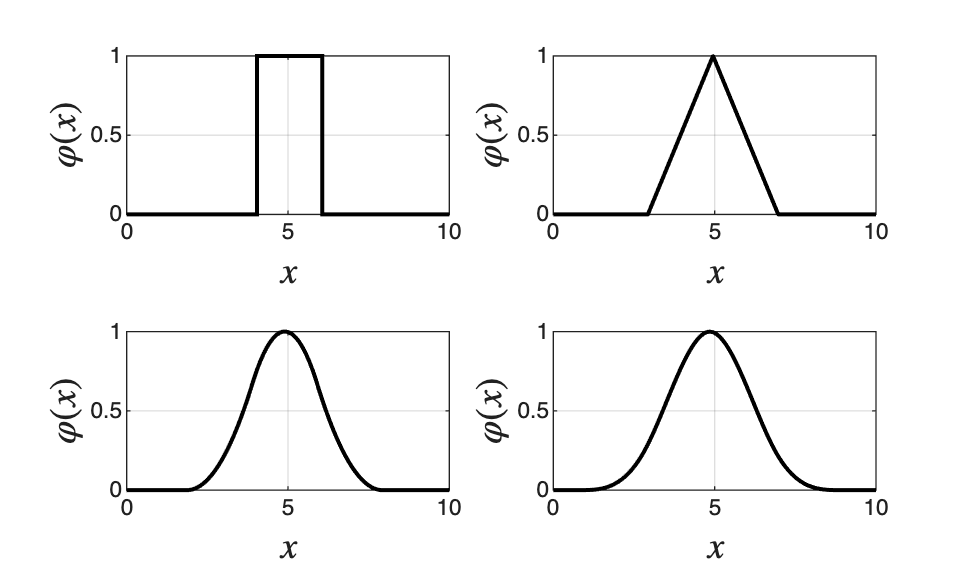

phi=f;

subplot(2,2,1)
stairs(t,phi/max(phi),'black','LineWidth',1.5)
grid on
ylabel('$\varphi(x)$','Interpreter','Latex','FontSize',14)
xlabel('$x$','Interpreter','Latex','FontSize',14)
    
for k=1:3;
    phi=conv(phi,f,'same');
    phi=phi;
    figure(1)
    subplot(2,2,k+1)
    plot(t,phi/max(phi),'black','LineWidth',1.5)
    grid on
    ylabel('$\varphi(x)$','Interpreter','Latex','FontSize',14)
    xlabel('$x$','Interpreter','Latex','FontSize',14)
end
print -depsc ch6_clt_convolutions.eps

## Note

As in the book, repeated convolution progressively smooths the pdf toward a Gaussian: this is the central limit theorem.